%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%                                                %%%%%%%%
%%%%%%%%          Seyyed Erfan Mohammadi                %%%%%%%%
%%%%%%%%        Describe topoplot with imagesc          %%%%%%%%
%%%%%%%%            Lecturer:Dr.Soltani                 %%%%%%%%
%%%%%%%%                                                %%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Load in EEG data.

clear all;
close all;
clc;
load sampleEEGdata.mat;

### Get cartesian coordinates of channles.

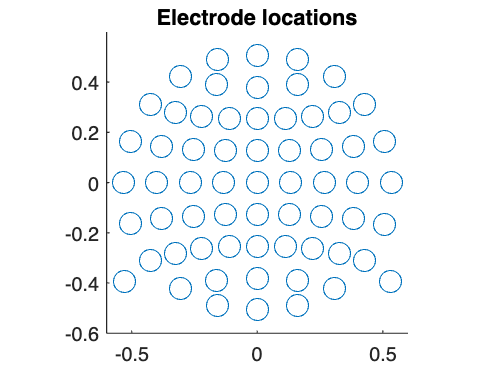

% [x,y] = pol2cart(theta,rho)

% theta is the counterclockwise angle in the x-y plane measured 
% in radians from the positive x-axis.

% rho is the distance from the origin to a point in the x-y plane.
[elocsX,elocsY] = pol2cart(pi/180*[EEG.chanlocs.theta],[EEG.chanlocs.radius]);

% plot electrode locations
scatter(elocsY,elocsX,100);
axis([-.6 .6 -.6 .6]);
axis square;
title('Electrode locations');

### Meshgrid for interpolation.

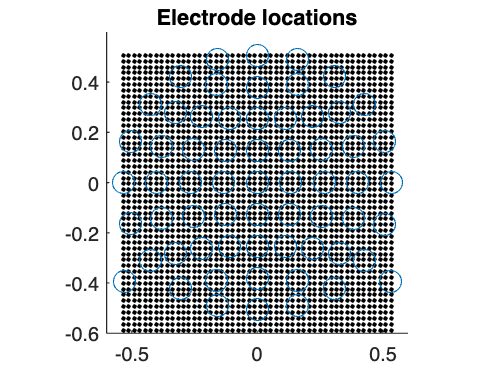

% define XY points for interpolation
interp_detail = 50;
interpX = linspace(min(elocsX),max(elocsX),interp_detail);
interpY = linspace(min(elocsY),max(elocsY),interp_detail);

% c is a function that creates 2D grid locations based on 1D inputs
[gridX,gridY] = meshgrid(interpX,interpY);

% let's look at these matrices
hold on;
plot3(gridY(:),gridX(:),-ones(1,interp_detail^2),'k.');

### Find mean of all epoch in special timepoint and interpolate it on 2D.

timepoint2plot = 200; % in ms

% convert time point from ms to index
[~,timepointidx] = min(abs(EEG.times-timepoint2plot));

% data from this frequency from some other matrix
dat = double( mean(EEG.data(:,timepointidx,:),3) );

% now interpolate the data on a 2D grid
interpFunction = scatteredInterpolant(elocsY',elocsX',dat);
topodata = interpFunction(gridX,gridY);

### Plot this code with imagesc.

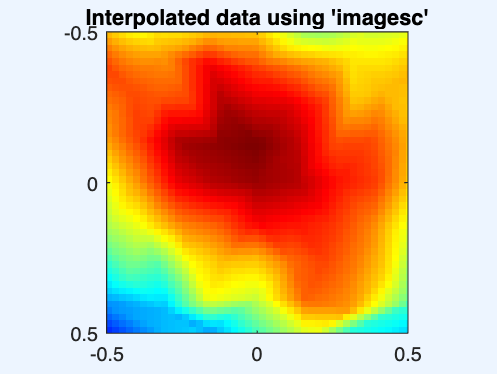

% pixelated image
clf;
imagesc(interpX,-interpY,topodata);
axis([-.5 .5 -.5 .5]);
axis square;
title('Interpolated data using ''imagesc''');

### Plot with eeglab toolbox.

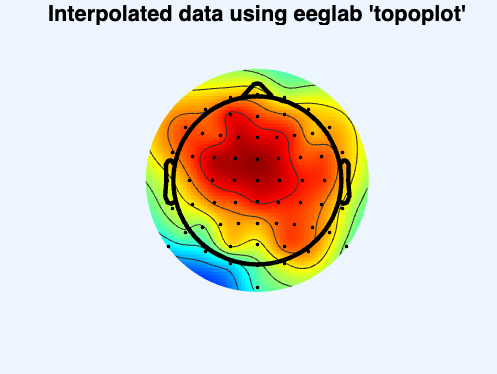

% eeglab function
clf;
topoplot(dat,EEG.chanlocs); % eeglab's topoplot function
title('Interpolated data using eeglab ''topoplot''');;